# Square Linear Systems: Introduction

clear, close all, format compact, format short g

## Fitting Population Data

The following are the U.S. Census data from 1980.

year = (1980:10:2020)';
pop = [226.546;
       248.710;
       281.422;
       308.746;
       332.639];

**Question.** How do we estimate population in other years?

- Interpolate (using a polynomial)!

x = year - 1980;
y = pop;
n = length(x);
V = x.^(0:n-1);

Solve $V \mathbf{c} = \mathbf{y}$ for $\mathbf{c}$:

c = V\y

c =        226.55
      0.71047
      0.21443
   -0.0071293
   7.4554e-05


**Post-Processing Interpolation Result.**

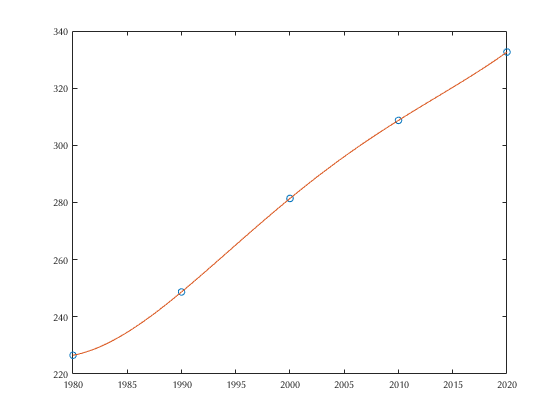

clf1
plot(x+1980, y, 'o')
hold on
xx = linspace(x(1), x(end), 100);
yy = polyval(flip(c), xx);
plot(xx+1980, yy)

## Solving Linear Systems Using Backslash (`\`)

For a square matrix $A$, the command `A\b` is mathematically equivalent to $A^{-1} \mathbf{b}$.

A = magic(3)
b = [1; 2; 3];
x = A\b

To check the answer, compute the *residual*. We hope it is small (close to the machine epsilon)

residual = b - A*x

If the matrix is singular, MATLAB still provides an answer with a warning.

S = [0 1;
     0 0]; % singular matrix
beta = [1; 2];
x = S\beta

## Triangular Systems

### Upper Triangular System and Backward Substitution

The upper triangular system $U\mathbf{x} = \mathbf{b}$ with


$$\left\lbrack \begin{array}{cccc}
u_{11}  & u_{12}  & \cdots  & u_{1n} \\
0 & u_{22}  & \cdots  & u_{2n} \\
\vdots  & \vdots  & \ddots  & \vdots \\
0 & 0 & \cdots  & u_{n\;n} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
\vdots \\
x_n 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
b_1 \\
b_2 \\
\vdots \\
b_n 
\end{array}\right\rbrack$$


is solvd by *backward substitution*:


$$\begin{array}{l}
x_n =\frac{b_n }{u_{n\;n} },\\
x_i =\frac{b_i -\sum_{j=i+1}^n u_{i,j} x_j }{u_{i\;i} },i=n-1,n-2,\dots ,2,1\ldotp 
\end{array}$$


Below is a MATLAB function m-file solving an upper triangular system using this algorithm. 

help backsub

**Testing the code:**

Set up an example

A = magic(5)

A =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9


U = triu(A)

U =     17    24     1     8    15
     0     5     7    14    16
     0     0    13    20    22
     0     0     0    21     3
     0     0     0     0     9


b = ones(5,1);

Solve it via backward substitution:

x = backsub(U,b)

Check the residual:

b - U*x

### Lower Triangular System and Forward Elimination

#### Question 1

As shown in the previous section, 

(a) Write down the general forward elimination formula to solve the lower triangular system $L\mathbf{x} = \mathbf{b}$ with

$\left\lbrack \begin{array}{cccc}
\ell_{11}  & 0 & \cdots  & 0\\
\ell_{21}  & \ell_{22}  & \cdots  & 0\\
\vdots  & \vdots  & \ddots  & \vdots \\
\ell_{n\;1}  & \ell_{n\;2}  & \cdots  & \ell_{n\;n} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
\vdots \\
x_n 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
b_1 \\
b_2 \\
\vdots \\
b_n 
\end{array}\right\rbrack$.

(You may type up the formula or simply insert a photo of your handwritten solution.)

(b) Complete the following function m-file (`forelim.m`) which implements the formula found in (a).

## Functions Used in This File

function x = backsub(U,b)
% BACKSUB   Solve an upper triangular linear system.
% Input:
%   U    upper triangular square matrix (n by n)
%   b    right-hand side vector (n by 1)
% Output:
%   x    solution of Ux=b (n by 1 vector)
n = length(U);
x = zeros(n,1);
for i = n:-1:1
    x(i) = ( b(i) - U(i,i+1:n)*x(i+1:n) ) / U(i,i);
end
end